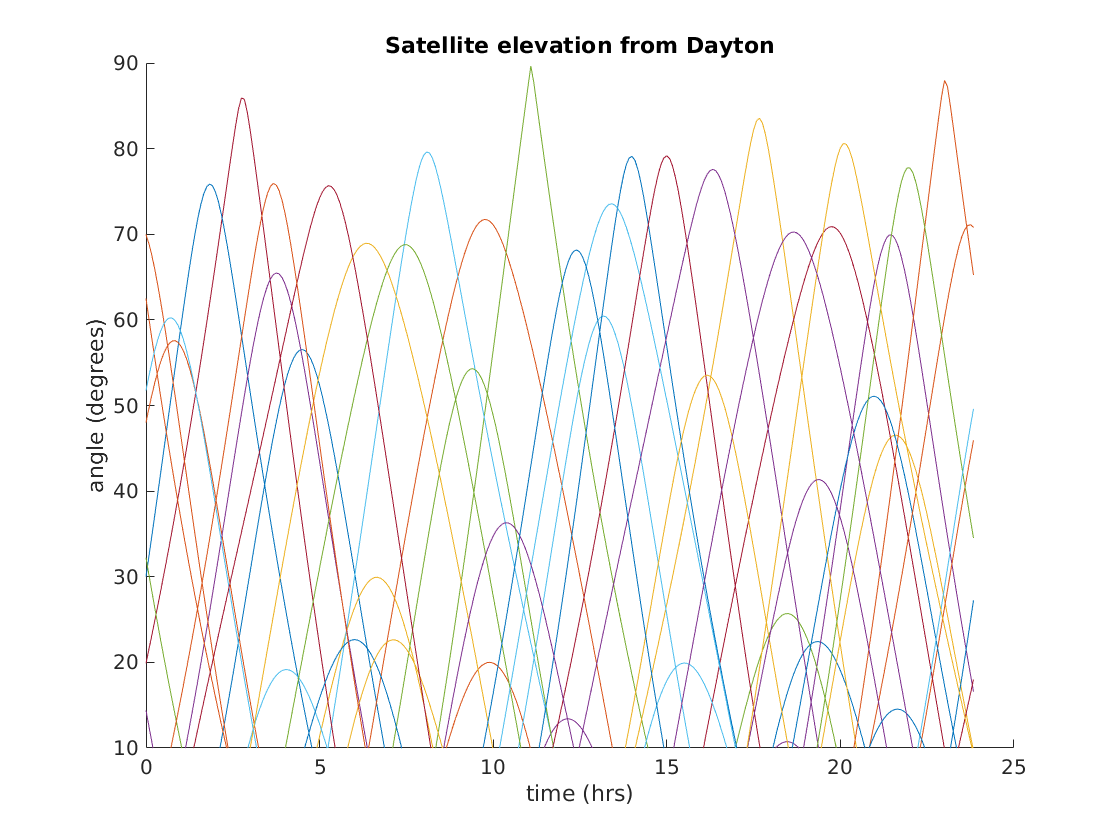

clear
clf
clc
load_eph_file('6jan2018.eph',559800)


AFIT_ECEF = [505988.59 -4882288.52 4059595.52];
afit_matrix = elevation_matrix(AFIT_ECEF);

figure();
hold on
time = [518400:5*60:604200];
time_hour = mod(time/3600,24);
for prn = 1:32
    plot(time_hour, afit_matrix(:,prn));
end
set(gca,'YLim', [10 90]);
title('Satellite elevation from Dayton')
xlabel('time (hrs)')
ylabel('angle (degrees)')

north_pole = lla2ecef(pi/2,0,0);
np_mat = elevation_matrix(north_pole)

np_mat =   -61.9370   15.0666  -33.0181   34.3513   42.5219   -9.1611   25.0360  -20.9502   38.2011  -45.8085  -54.4838  -37.9159   -7.8564  -46.3804  -23.9199   44.5344  -58.9279  -24.1760  -48.8214   13.4307   22.5641  -44.8254   17.4869  -60.3829  -14.9821   41.5491    4.3051  -40.8514   32.8014    4.7843   -6.8363  -57.2472
  -62.0048   13.0614  -34.7456   32.5589   43.2485  -11.1405   26.9097  -19.0405   36.7676  -44.2892  -53.5648  -39.5948   -5.8575  -47.8743  -22.0867   45.4507  -59.8146  -22.3539  -50.2298   15.3987   24.4134  -46.2720   15.4855  -60.0288  -16.9042   40.4028    6.3934  -39.1253   30.9516    6.7880   -8.7918  -58.1442
  -61.9428   11.0466  -36.4480   30.7066   43.8050  -13.1059   28.7456  -17.1136   35.2365  -42.7333  -52.5753  -41.2456   -3.8461  -49.3221  -20.2338   46.1877  -60.5939  -20.5161  -51.5902   17.3541   26.2281  -47.6738   13.4703  -59.5590  -18.8097   39.1292    8.4860  -37.3715   29.0499    8.7931  -10.7350  -58.9461
  -61.7518    9.0251  -38.12

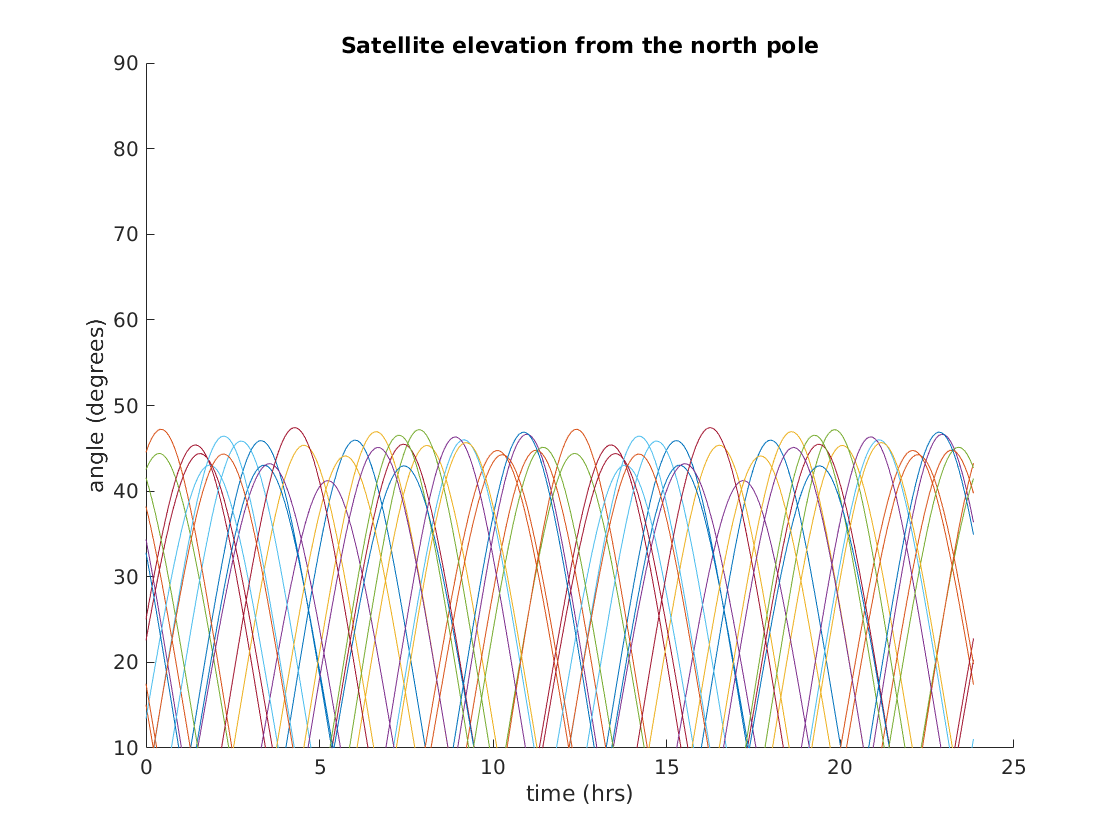


figure();
hold on
time = [518400:5*60:604200];
time_hour = mod(time/3600,24);
for prn = 1:32
    plot(time_hour, np_mat(:,prn));
end
set(gca,'YLim', [10 90]);
title('Satellite elevation from the north pole')
xlabel('time (hrs)')
ylabel('angle (degrees)')

equator = lla2ecef(0,0,0);
eq_mat = elevation_matrix(equator)

eq_mat =   -22.4092  -51.7704  -36.2240   32.2450  -28.0552  -76.3354  -55.7763   -3.2918  -35.5271   40.3318  -15.3065    3.8184  -38.4287   27.2254  -17.1653    2.1753  -46.8068   43.2288  -48.8555    9.8900   42.0932  -24.3498  -20.9418  -10.6400   29.7596   23.2992   14.3928  -56.6783    0.5438  -74.6604   67.3950   25.5953
  -20.8091  -52.9406  -35.5611   33.8485  -29.2396  -76.8086  -54.2301   -3.0509  -35.0290   41.8241  -14.1172    3.0566  -38.4794   26.7068  -17.4847    3.4101  -46.2417   43.4862  -48.3650    8.8457   39.9415  -23.3528  -20.5161  -12.2517   29.5040   24.9054   14.3263  -57.4247   -0.0537  -73.0454   68.4540   25.0311
  -19.2126  -54.0641  -34.8474   35.4882  -30.4542  -77.0826  -52.6843   -2.8332  -34.5651   43.3233  -12.9562    2.2428  -38.5077   26.1999  -17.7867    4.6965  -45.7045   43.6505  -47.8879    7.7520   37.8238  -22.3094  -20.1184  -13.8359   29.1699   26.5601   14.2533  -58.1485   -0.6067  -71.4341   69.2354   24.5027
  -17.6216  -55.1370  -34.08

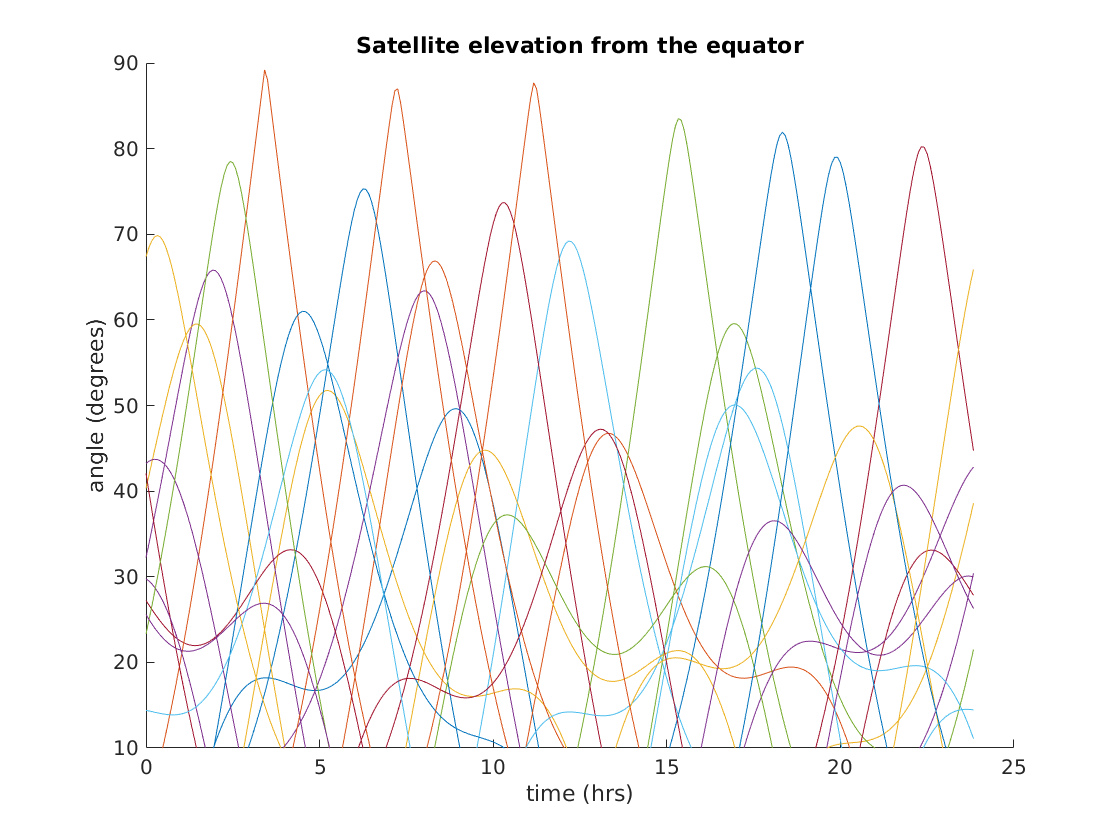


figure();
hold on
time = [518400:5*60:604200];
time_hour = mod(time/3600,24);
for prn = 1:32
    plot(time_hour, eq_mat(:,prn));
end
set(gca,'YLim', [10 90]);

title('Satellite elevation from the equator')
xlabel('time (hrs)')
ylabel('angle (degrees)')

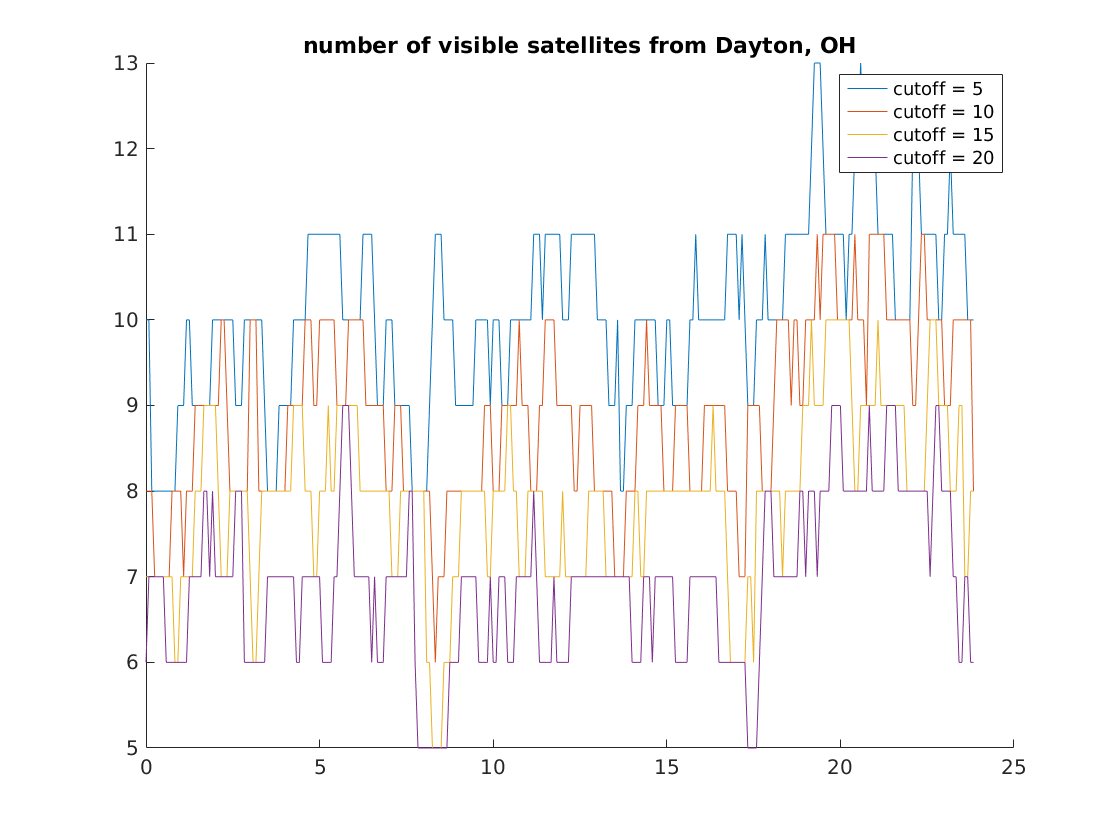

%task B
figure();
hold on


plot(time_hour,visSats(5,afit_matrix))
plot(time_hour,visSats(10,afit_matrix))
plot(time_hour,visSats(15,afit_matrix))
plot(time_hour,visSats(20,afit_matrix))

title("number of visible satellites from Dayton, OH")
legend('cutoff = 5','cutoff = 10','cutoff = 15','cutoff = 20')

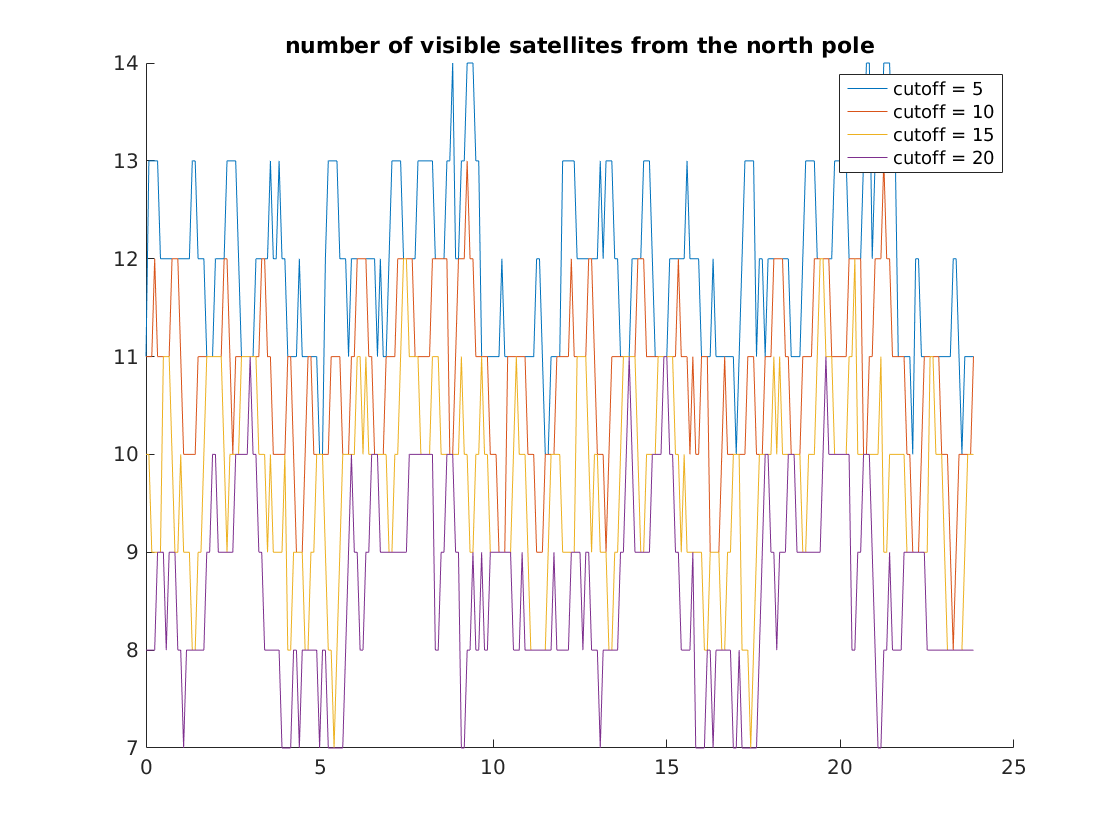


figure();
hold on
for i = 5:5:20
    plot(time_hour,visSats(i,np_mat))
end
title("number of visible satellites from the north pole")
legend('cutoff = 5','cutoff = 10','cutoff = 15','cutoff = 20')

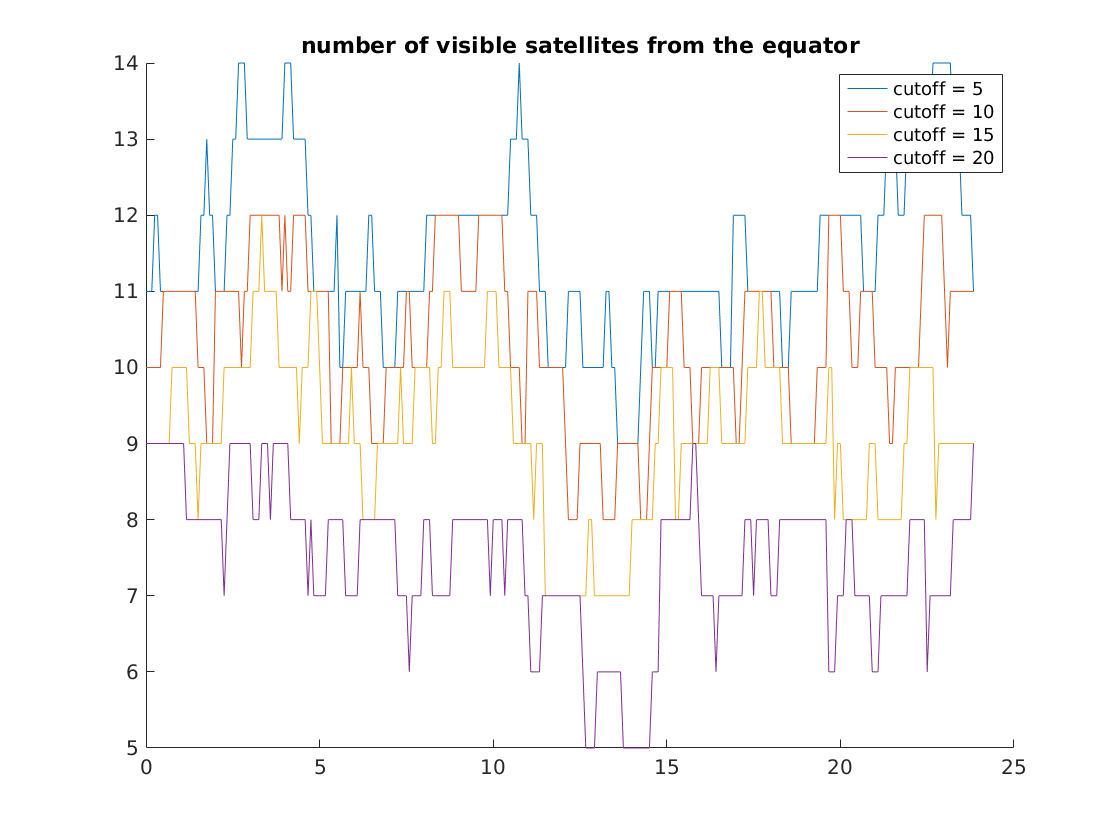



figure();
hold on
for i = 5:5:20
    plot(time_hour,visSats(i,eq_mat))
end
title("number of visible satellites from the equator")
legend('cutoff = 5','cutoff = 10','cutoff = 15','cutoff = 20')